## System Identification for Arduino Engineering Kit Motors

% Discrete state space model for Left Motor

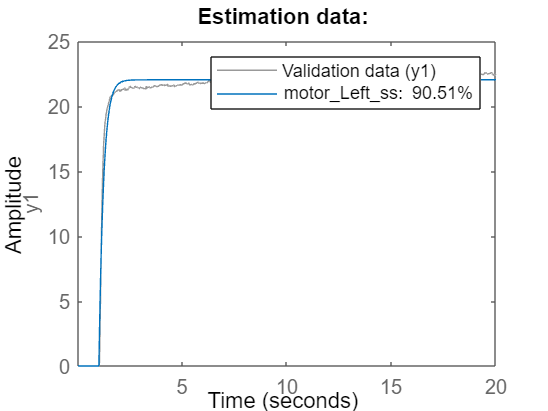

% Create object for time series data
estimationData = iddata(y_wL,u,0.01);

% Estimate state-space model
motor_Left_ss = ssest(estimationData,1,'Ts',estimationData.Ts);

% Display results
compare(estimationData,motor_Left_ss);
clear estimationData;
title('Estimation data:');

% Discrete state space model for Right Motor

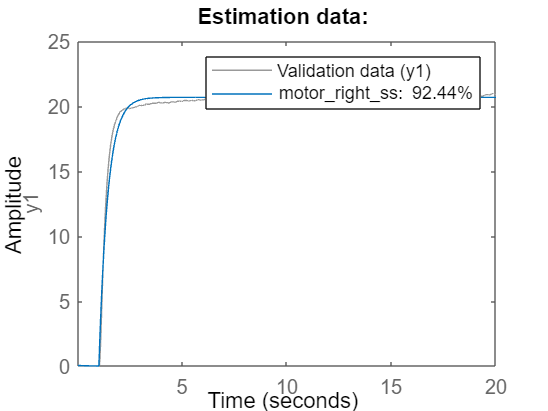

% Create object for time series data
estimationData2 = iddata(y_wR,u,0.01);

% Estimate state-space model
motor_right_ss = ssest(estimationData2,1,'Ts',estimationData2.Ts);

% Display results
compare(estimationData2,motor_right_ss);
clear estimationData2;
title('Estimation data:');

save Rover_Motor_Models motor_right_ss motor_Left_ss % save post-processed measurements